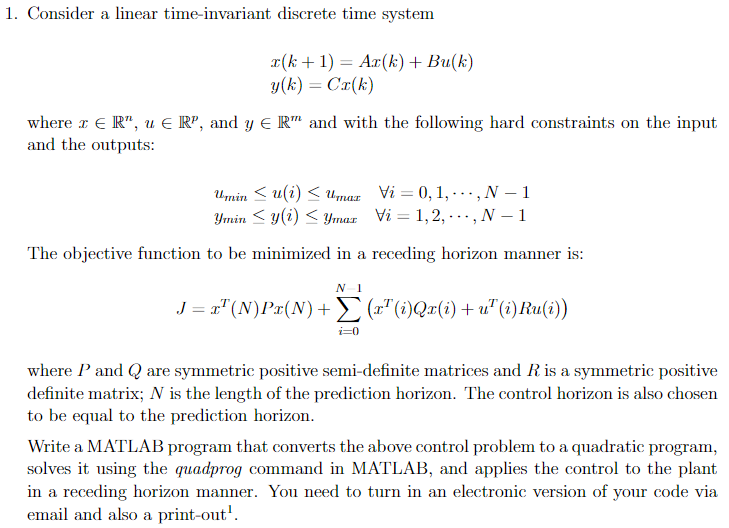

Below is a sample code to test out the get_QP function which forms the QP matrices and do_MPC function which calculates the receeding horizon controller for the given system.

clc;
clear;

dT = 0.1;
N = 10;
max_iter = 10;

A = [1 0 0;1 2 0;1 2 3].*dT;
A_d = A.*dT + eye(3);
B = ones(3,2);
B_d = B.*dT;
C = eye(3,3);

Q_i = 1e5*eye(3,3);
R_i = 0.1*eye(2,2);
P = 1e6*eye(3,3);

p = size(B,2);
m = size(C,2);

x0 = [1;1;1];

% constraints
%u_min = [-3; -5]; u_max = [5; 5];
%y_min = -5*ones(m,1); y_max = 5*ones(m,1);

% no constraints
u_min = []; u_max = [];
y_min = []; y_max = [];

X = []; U = []; T = [];

% get QP matrices
[F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP(A_d,B_d,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max);

% simulate MPC controller
x = x0; t = 0;
for i = 1:max_iter
    T = [T, t];
    if(isempty(A_ineq))
        u = do_MPC(G,x'*F',[],[],p);
    else
        u = do_MPC(G,x'*F',A_ineq,b_ineq+b_ineq_x0*x,p);
    end
    X = [X, x];
    x = A*x + B*u;
    U = [U, u]; t = i*dT;
end 

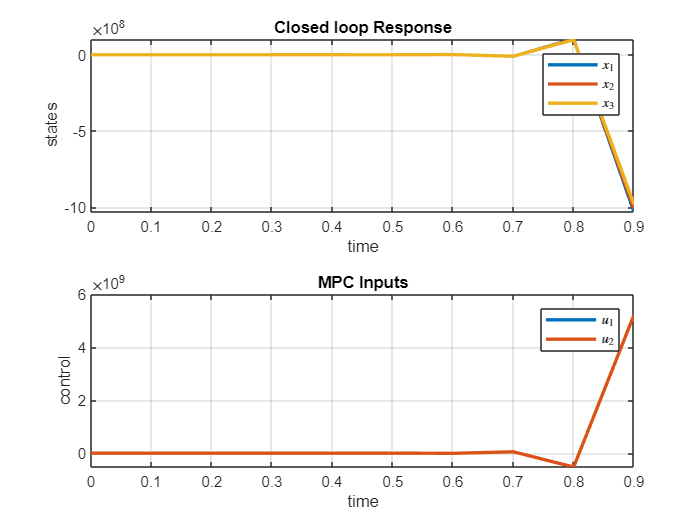


% plot
tiledlayout('flow')
nexttile
plot(T,X, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')
nexttile
plot(T,U,'LineWidth',2); grid on;
title(sprintf('MPC Inputs'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_1$', '$u_2$');
set(LEG,'interpreter','latex')

function u = do_MPC(G,F,A_ineq,B_ineq,p)
    % Inputs
    % G (augmented cost)                        : p(N) x p(N)
    % F (augmented cost)                        : p(N) x 1
    % augmented cost                            : 1/2 * X^T * G * X + X^T * F * x0
    % A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
    % b_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
    % b_ineq_x0 (augmented ineq constraint cx)  : 2(p+m)(N) x 1
    % augmented ineq constraint                 : A_ineq * X <= b_ineq + b_ineqx0 * x0
    % x0 (intial condititon for each horizon)   : n x 1
    % u_min is min the control bound            : scalar
    % u_max is max the control bound            : scalar
    % y_min is min the output bound             : scalar
    % y_max is min the output bound             : scalar
    % Q_i and R_i is assumed to be constant for i = 1 to N
    % Outputs
    % u (MPC output)                : p x 1
    options = optimoptions('quadprog','Display','off');
    U = quadprog(G,F,A_ineq,B_ineq,[],[],[],[],[],options);
    u = U(1:p);
    
end

function [F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP(A,B,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max)
    % Inputs
    % A (system dynamics)                       : n x n
    % B (control input)                         : n x p
    % C (system output)                         : n x m
    % P (termail cost)                          : n x 1
    % Q_i (state cost for stage i)              : n(N-1) x n(N-1)
    % R_i (control cost)                        : p(N-1) x p(N-1)
    % N is prediction horizon                   : scalar
    % u_min is min the control bound            : scalar
    % u_max is max the control bound            : scalar
    % y_min is min the output bound             : scalar
    % y_max is min the output bound             : scalar
    % Q_i and R_i is assumed to be constant for i = 1 to N
    % Augments
    % Q_hat (augmented Q)                       : n(N) x n(N)
    % R_hat (augmented R)                       : p(N) x p(N)
    % A_hat (augmented A)                       : n(N) x n(N)
    % B_hat (augmented B)                       : n(N) x p(N)
    % M_hat (augmented M)                       : (2(p+m)+2m)(N) x n(N)
    % E_hat (augmented E)                       : (2(p+m)+2m)(N) x p(N)
    % b_hat (augmented E)                       : (2(p+m)+2m)(N) x 1(N)
    % Outputs
    % G (augmented cost)                        : p(N) x p(N)
    % F (augmented cost)                        : p(N) x 1
    % augmented cost                            : 1/2 * X^T * G * X + X^T * F * x0
    % A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
    % b_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
    % b_ineq_x0 (augmented ineq constraint cx)  : 2(p+m)(N) x 1
    % augmented ineq constraint                 : A_ineq * X <= b_ineq + b_ineqx0 * x0

    
    n = size(A,2); % state dimension
    p = size(B,2); % control dimension
    m = size(C,1); % output dimension

    A_hat = zeros(n*N,n);
    b = [];
    B_hat = zeros(n*N,p*N);

    for i = 1:N
        A_hat((i-1)*n+1:i*n,:) = A^i;
        b = [A^(i-1)*B, b];
        B_hat((i-1)*n+1:i*n,1:i*p) = b;
    end

    %% Augmented cost
    Q_hat = [];
    R_hat = [];
    for i = 1:N-1
        Q_hat = blkdiag(Q_hat, Q_i);
        R_hat = blkdiag(R_hat, R_i);
    end
    % add the cost for terminal states and control
    Q_hat = blkdiag(Q_hat,P);
    R_hat = blkdiag(R_hat,R_i);

    % Augmented cost: 1/2 * X^T * G * X + X^T * F * x0 
    G = 2*(R_hat + B_hat'*Q_hat*B_hat);
    F = 2*B_hat'*Q_hat*A_hat;
    
    %% Augmented inequality constraint
    M_i = []; E_i = []; b_i = [];
    M_N = []; b_N = [];
    
    no_con = 1; % True if constraints = []
    if(~isempty(u_min))
        no_con = 0;
        M_i = [M_i; zeros(p,n)];
        E_i = [E_i; -eye(p,p)];
        b_i = [b_i; -u_min];
    end
    
    if(~isempty(u_max))
        no_con = 0;
        M_i = [M_i; zeros(p,n)];
        E_i = [E_i; eye(p,p)];
        b_i = [b_i; u_max];
    end

    if(~isempty(y_min))
        no_con =0;
        M_i = [M_i; -C];
        E_i = [E_i; zeros(m,p);];
        b_i = [b_i; -y_min];
        M_N = [M_N; -C];
        b_N = [b_N; -y_min];
    end
    
    if(~isempty(y_max))
        no_con = 0;
        M_i = [M_i; C];
        E_i = [E_i; zeros(m,p)];
        b_i = [b_i; y_max];
        M_N = [M_N; C];
        b_N = [b_N; y_max];
    end
    
    M_hat = [];
    M_0 = [];  
    E_hat = E_i; % initial
    b_hat = b_i; % initial
    for i = 1:N-1
        M_hat = blkdiag(M_hat, M_i);
        E_hat = blkdiag(E_hat, E_i);
        b_hat = [b_hat; b_i];
        M_0 = [M_0; zeros(size(M_i))];
    end

    % get the last elements for i=N
    M_hat = blkdiag(M_hat, M_N);
    M_0 = [M_0; zeros(size(M_i))];
    if(isempty(M_N))
        M_hat = [M_hat, zeros(size(M_hat,1),n)];
    end
    b_hat = [b_hat; b_N];

    % augment zeros for to match dimensions for i=N
    M_hat = [zeros(size(M_i,1),size(M_hat,2)); M_hat];
    M_0 = [M_0; zeros(size(M_N))];
    E_hat = [E_hat; zeros(size(M_N,1),size(E_hat,2))];
    
    % Augmented inequality constraint: A_ineq * X <= b_ineq + b_ineqx0 * x0
    if(no_con)
        A_ineq = [];
        b_ineq_x0 = [];
        b_ineq = [];        
    else
        A_ineq = M_hat*B_hat + E_hat;
        b_ineq_x0 = -(M_hat*A_hat + M_0);
        b_ineq = b_hat;
    end   
end